# TPA 3 MPC Grupo 10

A contiunación se obtiene el modelo discrete en espacio de estados a partir del modelo de orden 6 obtenido en el TP1 (identificación)

close all; clc;
s = tf('s');

% addpath(genpath('...'));
% savepath

% modelo de orden 6
model_6 = 1.261e06/(s^6 + 75.11* s^5 + 1869* s^4 + 2.523e04* s^3 + 1.888e05* s^2 + 7.568e05* s + 1.26e06)


model_6 =
 
                                  1.261e06
  ------------------------------------------------------------------------
  s^6 + 75.11 s^5 + 1869 s^4 + 25230 s^3 + 188800 s^2 + 756800 s + 1.26e06
 
Continuous-time transfer function.
Model Properties


% model_6 = 1/(( (10e3)*(10e-6)*s + 1 )^6)

[p, z] = pzmap(model_6);
high_freq_pole = abs(max(p));

% TIEMPO DE MUESTREO
Ts = round(1/(5*high_freq_pole), 3)

Ts = 0.0050


model_discrete = c2d(model_6, Ts)


model_discrete =
 
  2.594e-11 z^5 + 1.402e-09 z^4 + 7.044e-09 z^3 + 6.676e-09 z^2 + 1.194e-09 z + 1.984e-11
  ---------------------------------------------------------------------------------------
          z^6 - 5.647 z^5 + 13.28 z^4 - 16.64 z^3 + 11.72 z^2 - 4.397 z + 0.6869
 
Sample time: 0.005 seconds
Discrete-time transfer function.


[model_A, model_B, model_C, model_D] = tf2ss(model_discrete.Numerator{1}, model_discrete.Denominator{1});

Se verifican los modelos continuos y discretos comparando sus respuestas al escalón

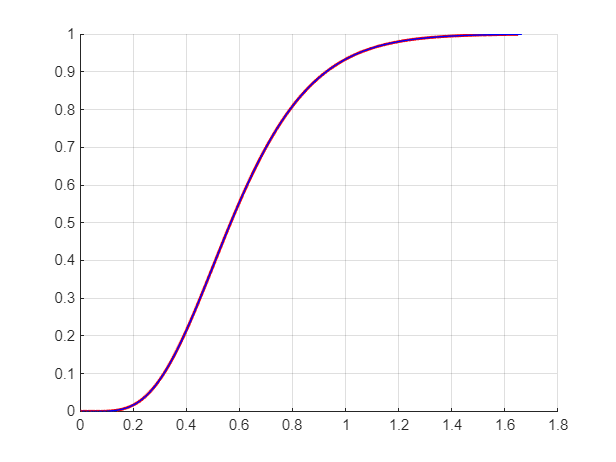

[cont_y, cont_t] = step(model_6);
[disc_y, disc_t] = step(model_discrete);

figure; hold on; grid on;
plot(cont_t, cont_y, 'r', 'LineWidth', 2);
plot(disc_t, disc_y, 'b', 'LineWidth', 1);

Ahora se obtiene el modelo en espacio de estados pero considerando variaciones en la entrada en de las muestras $\Delta U$(modelo incremental = inc_model)

A_expanded = [model_A, model_B; zeros(1, length(model_A)), ones(1, 1)];
B_expanded = [model_B; ones(1, 1)];
C_expanded = [model_C, zeros(1,1)];

inc_model = ss(A_expanded, B_expanded, C_expanded, 0, Ts)


inc_model =
 
  A = 
            x1       x2       x3       x4       x5       x6       x7
   x1    5.647   -13.28    16.64   -11.72    4.397  -0.6869        1
   x2        1        0        0        0        0        0        0
   x3        0        1        0        0        0        0        0
   x4        0        0        1        0        0        0        0
   x5        0        0        0        1        0        0        0
   x6        0        0        0        0        1        0        0
   x7        0        0        0        0        0        0        1
 
  B = 
       u1
   x1   1
   x2   0
   x3   0
   x4   0
   x5   0
   x6   0
   x7   1
 
  C = 
              x1         x2         x3         x4         x5         x6         x7
   y1  2.594e-11  1.402e-09  7.044e-09  6.676e-09  1.194e-09  1.984e-11          0
 
  D = 
       u1
   y1   0
 
Sample time: 0.005 seconds
Discrete-time state-space model.


Se cargan las matrices F y $\phi \;$

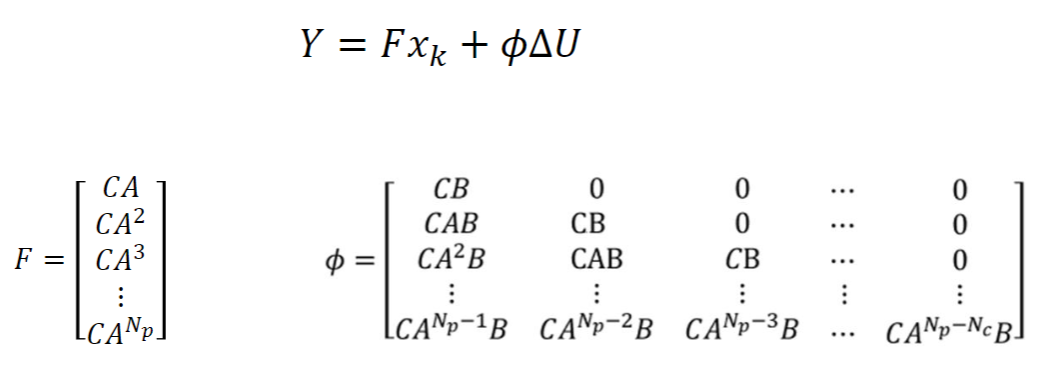

## Para calcular Np consideré que si Ts=0.1 y Tr=1.4 entonces entran 14 muestras hasta que se extinguen los transitorios

# IMPORTANTE: No se si lo anterior es cierto

% Np = round(1.4/Ts);
% Nc = 3;

% Esto genera F para un rango dinámico Np
% F_mat = zeros(Np, length(A_expanded));
% F_mat(1, :) = C_expanded*A_expanded;
% for i = 2:Np
%     F_mat(i, :) = F_mat(i-1, :)*A_expanded;
% end
% F_mat
% 
% % Esto genera phi para un rango dinámico de Np y Nc
% phi_mat = zeros(Np, Nc);
% for j = 1:Nc
%     for i = 1:Np
%         if (i < j)
%             phi_mat(i, j) = 0;
%         elseif (i == j)
%             phi_mat(i, j) = C_expanded*B_expanded;
%         else
%             phi_mat(i, j) = C_expanded*(A_expanded^(Np-j))*B_expanded;
%         end
%     end
% end
% phi_mat

% reference = 1;
% [Phi_Phi,Phi_F,Phi_R,A_e, B_e,C_e] = mpcgain(A_expanded, B_expanded, C_expanded, Nc, Np, reference);

A continuación se calculan las entradas $\Delta U$de manera analítica

% states = zeros(length(A_expanded), 1);
% ref_weight_mat = 0.1*eye(Nc);
% Rs = ones(1, Np);
% dU = ((((phi_mat')*phi_mat+ref_weight_mat)^(-1))*(phi_mat'))*(Rs*reference-F_mat*states)

% Rs*reference
% F_mat*states
% (Rs*reference-F_mat*states)

states = zeros(length(A_expanded), 1);
% ref_weight_mat = 0.1*eye(Nc);
% dU = ((Phi_Phi + ref_weight_mat)^(-1)) * ( Phi_R - Phi_F *  states)

Ahora se hace una simulación de la acción de control en diferencias

Np = round(1.4/Ts);
Nc = 3;
reference = 1;
rw = 0.1;
ref_weight_mat = rw*eye(Nc);
[Phi_Phi,Phi_F,Phi_R,A_e, B_e,C_e] = mpcgain(A_expanded, B_expanded, C_expanded, Nc, Np, reference);

BarRs =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1



writeMatrixToHeader(Phi_Phi, 'phi_phi.h', 'phi_phi');

Matrix exported successfully to phi_phi.h as phi_phi.


writeMatrixToHeader(Phi_F, 'phi_f.h', 'phi_f');

Matrix exported successfully to phi_f.h as phi_f.


writeMatrixToHeader(Phi_R, 'phi_r.h', 'phi_r');

Matrix exported successfully to phi_r.h as phi_r.


writeMatrixToHeader(A_e, 'Ae.h', 'Ae');

Matrix exported successfully to Ae.h as Ae.


writeMatrixToHeader(B_e, 'Be.h', 'Be');

Matrix exported successfully to Be.h as Be.


writeMatrixToHeader(C_e, 'Ce.h', 'Ce');

Matrix exported successfully to Ce.h as Ce.


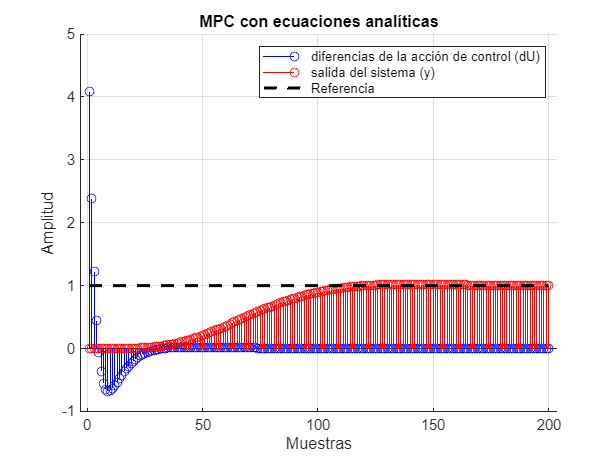


sim_length = 200;
x = zeros(1, sim_length);
y = zeros(1, sim_length);

for i = 1:sim_length
    dU = ((Phi_Phi + ref_weight_mat)^(-1)) * ( Phi_R - Phi_F *  states);
    x(i) = dU(1);
    states = A_expanded*states + B_expanded*x(i); 
    y(i) = C_expanded*states;
end

fig = figure();
hold on; grid on;
ylabel('Amplitud');
% ylabel('Tensión [Volts]');
xlabel('Muestras');

stem(x, 'b');
stem(y, 'r');
plot(ones(1, length(y)), '--k', 'LineWidth', 2);

title('MPC con ecuaciones analíticas');
legend('diferencias de la acción de control (dU)', 'salida del sistema (y)', 'Referencia');

Ahora si quiero aplicar restricciones a la acción de control por ejemplo, no podría resolverlo de manera analítica, necesitaria usar un solver, por ejemplo empleo uno de la librería yamilp:

nx = length(A_expanded);                     
nu = 1;                      
ny = 1;                      

R = rw * eye(nu);

% YALMIP
u = sdpvar(Nc, nu);
x = sdpvar(nx, Np+1);
r = sdpvar(Np, ny);

constraints = [];
objective = 0;

for k = 1:Nc
    constraints = [constraints, x(:,k+1) == A_expanded*x(:,k) + B_expanded*u(k)];
    constraints = [constraints, -5 <= u(k) <= 5];
    objective = objective + (r(k) - C_expanded*x(:,k+1))' * (r(k) - C_expanded*x(:,k+1)) + u(k)' * R * u(k);
end

% Condiciones y coste
for k = Nc+1:Np
    constraints = [constraints, x(:,k+1) == A_expanded*x(:,k)];
    objective = objective + (r(k) - C_expanded*x(:,k+1))' * (r(k) - C_expanded*x(:,k+1));
end

ops = sdpsettings('verbose', 2);
controller = optimizer(constraints, objective, ops, {x(:,1), r(:)}, u(:));

% simulacion
state = zeros(nx, 1);             
r_sim = ones(Np, ny);          
sim_steps = 200;                
du = zeros(Nc, sim_steps); 
ys = zeros(sim_steps, 1);   

for k = 1:sim_steps
    [u_opt, diagnostics] = controller({state, r_sim});
    
    if diagnostics == 1
        error('Error con el controller/solver');
    end
    
    u_k = u_opt(1);
    du(1, k) = u_k;
    
    state = A_expanded*state + B_expanded*u_k;
    y_k = C_expanded*state;
    ys(k) = y_k;
end


Solver stopped prematurely.

quadprog stopped because it exceeded the iteration limit,
options.MaxIterations = 2.000000e+02.


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<

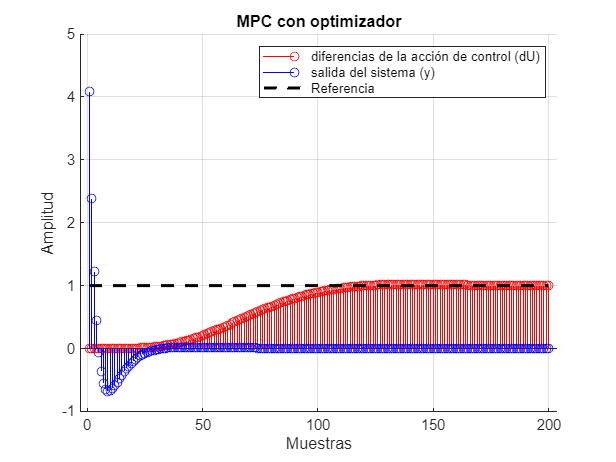


figure; hold on; grid on;
stem(ys, 'r');
stem(du(1, :), 'b');
plot(ones(1, length(ys)), '--k', 'LineWidth', 2);

title('MPC con optimizador');
ylabel('Amplitud');
xlabel('Muestras');
legend('diferencias de la acción de control (dU)', 'salida del sistema (y)', 'Referencia');

Ahora vuelvo a calcular lo mismo que antes pero aplicando las restricciones a la diferencia de accion de control

Era todo el objetivo de lo anterior, pero lo de antes es a modo de demostración que se llega a la misma resolución que de manera analítica

rest_u_inf = 0;
rest_u_sup = 5;

constraints = [];
objective = 0;

for k = 1:Nc
    constraints = [constraints, x(:,k+1) == A_expanded*x(:,k) + B_expanded*u(k)];
    constraints = [constraints, rest_u_inf <= u(k) <= rest_u_sup];
    objective = objective + (r(k) - C_expanded*x(:,k+1))' * (r(k) - C_expanded*x(:,k+1)) + u(k)' * R * u(k);
end

% Condiciones y coste
for k = Nc+1:Np
    constraints = [constraints, x(:,k+1) == A_expanded*x(:,k)];
    objective = objective + (r(k) - C_expanded*x(:,k+1))' * (r(k) - C_expanded*x(:,k+1));
end

ops = sdpsettings('verbose', 2);
controller = optimizer(constraints, objective, ops, {x(:,1), r(:)}, u(:));

% simulacion
state = zeros(nx, 1);             
r_sim = ones(Np, ny);          
sim_steps = 80;                
du = zeros(Nc, sim_steps); 
ys = zeros(sim_steps, 1);   

for k = 1:sim_steps
    [u_opt, diagnostics] = controller({state, r_sim});
    
    if diagnostics == 1
        error('Error con el controller/solver');
    end
    
    u_k = u_opt(1);
    du(1, k) = u_k;
    
    state = A_expanded*state + B_expanded*u_k;
    y_k = C_expanded*state;
    ys(k) = y_k;
end

Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.



                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    2.802940e+02    9.900e-01    1.491e-08


    1       2    2.800000e+02    4.950e-03    1.970e-01    1.706e+00
    2       4    2.800000e+02    2.487e-03    1.975e-01    4.265e-03
    3       6    2.800000e+02    1.250e-03    1.977e-01    2.143e-03
    4       8    2.800000e+02    6.281e-04    9.884e-02    1.077e-03
    5      10    2.800000e+02    3.156e-04    4.942e-02    5.412e-04
    6      12    2.800000e+02    1.586e-04    2.471e-02    2.721e-04
    7      14    2.800000e+02    7.969e-05    1.236e-02    1.368e-04


    8      16    2.800000e+02    4.005e-05    6.180e-03    2.235e-04
    9      18    2.800000e+02    2.013e-05    3.090e-03    1.998e-04
   10      20    2.800000e+02    1.011e-05    1.545e-03    4.571e-05
   11      22    2.800000e+02    5.085e-06    7.860e-04    2.203e-04
   12      24    2.800000e+02    2.558e-06    4.730e-04    1.813e-04
   13      26    2.800000e+02    1.287e-06    3.165e-04    6.645e-04
   14      27    2.800000e+02    7.761e-09    3.200e-05    5.908e-04
   15      28    2.800000e+02    4.914e-09    3.200e-05    1.288e-02
   16      29    2.800000e+02    2.839e-09    3.200e-05    1.072e-02
   17      31    2.800000e+02    1.883e-09    3.200e-05    1.152e-03
   18      33    2.800000e+02    1.162e-09    2.312e-05    1.426e-03
   19      35    2.800000e+02    6.181e-10    1.065e-05    6.475e-04
   20      37    2.800000e+02    3.158e-10    7.637e-06    4.098e-04
   21      39    2.800000e+02    1.668e-10    7.637e-06    4.827e-04


   22      51    2.800000e+02    7.951e-11    7.637e-06    1.035e-03


   23      58    2.800000e+02    8.789e-11    7.637e-06    9.265e-04
   24      60    2.800000e+02    8.764e-11    7.637e-06    7.981e-06
   25      62    2.800000e+02    7.585e-11    7.637e-06    3.250e-04
   26      65    2.800000e+02    6.343e-11    7.637e-06    1.436e-04


   27      77    2.800000e+02    6.048e-11    7.637e-06    1.275e-03
   28      79    2.800000e+02    6.022e-11    7.637e-06    3.195e-05
   29      82    2.800000e+02    4.365e-11    7.637e-06    3.237e-03


   30      95    2.800000e+02    3.287e-11    7.637e-06    1.909e-03

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
   31      97    2.800000e+02    3.148e-11    7.637e-06    2.148e-03


   32     108    2.800000e+02    2.641e-11    7.637e-06    7.078e-04


   33     115    2.800000e+02    2.508e-11    7.637e-06    2.044e-03
   34     118    2.800000e+02    2.461e-11    7.637e-06    8.280e-04


   35     126    2.800000e+02    1.825e-11    7.637e-06    1.789e-03
   36     128    2.800000e+02    3.819e-11    7.637e-06    1.229e-01
   37     129    2.800000e+02    4.101e-12    7.443e-06    3.263e-01


   38     140    2.800000e+02    1.747e-12    2.215e-06    2.936e-05
   39     143    2.800000e+02    1.748e-12    2.215e-06    8.211e-05


   40     156    2.800000e+02    1.195e-12    2.215e-06    1.903e-05
   41     158    2.800000e+02    1.201e-12    2.215e-06    5.385e-05
   42     160    2.800000e+02    7.698e-11    2.215e-06    2.316e+00
   43     162    2.800000e+02    1.872e-11    2.215e-06    5.169e-01
   44     164    2.800000e+02    3.591e-11    2.215e-06    6.699e+00
   45     165    2.800000e+02    1.604e-11    2.215e-06    4.897e+00


   46     188    2.800000e+02    6.554e-12    3.200e-07    1.995e-05

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.



                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    2.802940e+02    9.900e-01    1.491e-08


    1       2    2.800000e+02    4.950e-03    1.970e-01    1.706e+00
    2       4    2.800000e+02    2.487e-03    1.975e-01    4.266e-03
    3       6    2.800000e+02    1.250e-03    1.977e-01    2.144e-03
    4       8    2.800000e+02    6.281e-04    9.884e-02    1.079e-03
    5      10    2.800000e+02    3.156e-04    4.942e-02    5.444e-04
    6      12    2.800000e+02    1.586e-04    2.471e-02    2.787e-04
    7      14    2.800000e+02    7.971e-05    1.235e-02    1.564e-04
    8      16    2.800000e+02    4.006e-05    6.166e-03    1.198e-04
    9      18    2.800000e+02    2.014e-05    3.037e-03    4.013e-04
   10      20    2.800000e+02    1.014e-05    1.497e-03    6.317e-04
   11      22    2.800000e+02    5.100e-06    7.860e-04    4.645e-04
   12      24    2.800000e+02    2.576e-06    4.730e-04    3.155e-04
   13      26    2.800000e+02    1.368e-06    3.571e-04    6.170e-03
   14      27    2.800000e+02    7.254e-08    1.728e-04    1.084e-02
   15      29    2.800000e+02    5

   24      52    2.800000e+02    1.611e-09    9.347e-05    1.011e-02
   25      54    2.800000e+02    1.293e-09    7.351e-05    3.170e-03
   26      56    2.800000e+02    1.121e-09    6.938e-05    8.633e-03
   27      58    2.800000e+02    1.024e-09    6.938e-05    1.192e-02


   28      68    2.800000e+02    1.022e-09    6.938e-05    3.144e-02
   29      70    2.800000e+02    1.004e-09    6.938e-05    3.035e-04
   30      72    2.800000e+02    9.652e-10    6.938e-05    3.521e-03



                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
   31      83    2.800000e+02    9.676e-10    6.938e-05    9.363e-03
   32      85    2.800000e+02    9.670e-10    6.938e-05    7.024e-04
   33      87    2.800000e+02    9.670e-10    6.938e-05    7.888e-02


   34      98    2.800000e+02    9.681e-10    6.938e-05    5.509e-03
   35      99    2.800000e+02    9.572e-10    6.938e-05    3.208e-02
   36     105    2.800000e+02    7.399e-10    6.938e-05    1.074e+00
   37     112    2.800000e+02    6.393e-10    6.938e-05    5.192e-01
   38     114    2.800000e+02    9.293e-10    6.938e-05    3.162e+00
   39     116    2.800000e+02    2.890e-10    6.659e-05    6.634e-02
   40     118    2.800000e+02    7.725e-11    6.659e-05    2.585e+00


   41     141    2.800000e+02    3.838e-11    6.659e-05    3.619e-04
   42     144    2.800000e+02    3.835e-11    6.659e-05    2.464e-03


   43     156    2.800000e+02    2.459e-11    5.919e-05    2.519e-04
   44     159    2.800000e+02    2.455e-11    5.914e-05    1.593e-03
   45     161    2.800000e+02    1.201e-12    5.914e-05    3.526e+00


   46     200    2.800000e+02    8.731e-13    5.914e-05    1.104e-04
   47     203    2.800000e+02    8.576e-13    5.914e-05    2.249e-04


   48     216    2.800000e+02    7.082e-13    3.480e-05    5.265e-05
   49     219    2.800000e+02    7.068e-13    3.480e-05    5.522e-05


   50     233    2.800000e+02    6.091e-13    1.021e-05    3.522e-06
   51     234    2.800000e+02    4.162e-11    7.676e-06    1.411e+00
   52     235    2.800000e+02    1.471e-10    7.676e-06    8.405e+01
   53     236    2.800000e+02    2.564e-10    7.676e-06    1.925e+01
   54     237    2.800000e+02    1.167e-10    7.676e-06    5.995e+01
   55     238    2.799999e+02    1.137e-10    7.676e-06    1.823e+02
   56     239    2.799998e+02    7.926e-11    7.676e-06    6.763e+02
   57     240    2.799992e+02    7.534e-11    7.676e-06    3.334e+03
   58     241    2.799958e+02    2.001e-11    7.676e-06    1.813e+04
   59     242    2.799785e+02    5.139e-11    8.418e-06    9.352e+04
   60     243    2.798916e+02    2.110e-10    2.077e-05    4.697e+05

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
   61     244    2.794585e+02    1.950e-09    9.106e-05    2.339e+06
   62     245    2.773411e+02    

   86     274   -2.839815e+03    4.932e-06    1.537e-07    3.714e+01
   87     275   -2.988002e+03    2.372e-05    3.342e-02    8.021e+08
   88     276   -3.111670e+03    1.407e-05    6.134e-02    6.694e+08
   89     277   -3.324432e+03    2.122e-05    1.094e-01    1.152e+09
   90     278   -3.512554e+03    2.789e-05    1.518e-01    1.019e+09

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
   91     279   -3.671993e+03    2.503e-05    1.878e-01    8.634e+08
   92     280   -3.892730e+03    1.967e-05    2.376e-01    1.195e+09
   93     281   -4.119338e+03    2.801e-05    2.887e-01    1.227e+09
   94     282   -4.154455e+03    2.527e-05    2.967e-01    1.902e+08
   95     283   -4.154630e+03    2.360e-05    2.967e-01    9.510e+05


   96     287   -4.154636e+03    1.335e-03    2.960e-07    2.376e+05
   97     288   -4.066659e+03    3.386e-05    2.305e-02    4.765e+08
   98     289   -3.940444e+03    2.718e-05    5.240e-02    6.837e+08
   99     291   -3.792304e+03    1.884e-05    8.599e-02    8.023e+08


  100     306   -3.792304e+03    1.264e-05    3.259e-07    7.666e+01
  101     308   -3.792304e+03    1.276e-05    3.259e-07    1.533e+02
  102     310   -3.799919e+03    1.359e-05    1.751e-03    4.124e+07



figure; hold on; grid on;
stem(du(1, :), 'b');
stem(ys, 'r');
plot(ones(1, length(ys)), '--k', 'LineWidth', 2);

title('MPC con optimizador');
ylabel('Amplitud');
xlabel('Muestras');
legend('diferencias de la acción de control (dU)', 'salida del sistema (y)', 'Referencia');